# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*-------------------------------------------------------------------------------------------------------------------------------*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

*--------------------------------------------------------------------------------------------------------------------------------*

### **Interpreting Voltage Values from the EEG Signal**

- The unit of measurement of EEG is volts (typically, microvolts or μV);  

- For EEG (both time and frequency domain), microvolts are relative values, such that the microvolt recorded from an electrode is actually the change in the measured electrical potential between that electrode and a reference electrode: *these can be difficult to interpret in an absolute sense*

- First,  microvolt values will change depending on data processing and analysis decisions, including the choice of reference and the time period used for baseline subtraction.

- Second, that raw voltage values can be difficult to interpret is that microvolt values differ across subjects according to factors that may be of no interest to cognitive electrophysiologists: skull shape and thickness

- For this reason, you should not be concerned that *many time-frequency-based analyses transform the original data scale.*  e.g., decibel normalization for time-frequency power data; individual differences in raw values are eliminated, and thus the results can be more easily compared across electrodes, subjects, recording equipment, and publications.  

-----------------------------------------------------------------------------------------------------------

### **Interpreting and Asking Questions about Time-Frequency Results**  

*Frequency, Phase, Power*

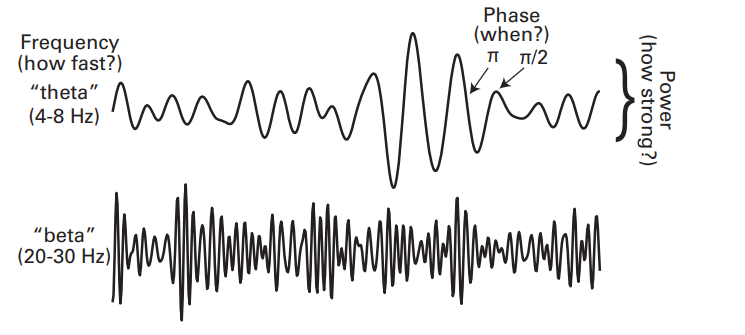

- **Background and Task-related activity. **Background activity refers to activity that is present in the data but is unmodulated by task events. This is why some form of baseline normalization is useful: baseline normalization removes or strongly attenuates patterns of activity that are present in the data but are unrelated to the task.

- **Phase-locked and non-phase-locked activity in task related activities. ***phase-locked *when its phase is the same or very similar on each trial (both time and frequency domain). *nonphase-locked *when its phase is different on each trial. (*Note: It is not entirely clear what mixture of physiological dynamics would result in phase-locked versus non-phase-locked activity (David, Kilner, and Friston 2006), although in general, non-phase-locked activity is taken as stronger evidence for the presence of oscillations.*)

- **Time-locked and non-time-locked: **whether you can see the task-related activity on time 0 in every trial (it could be phase locked or not)

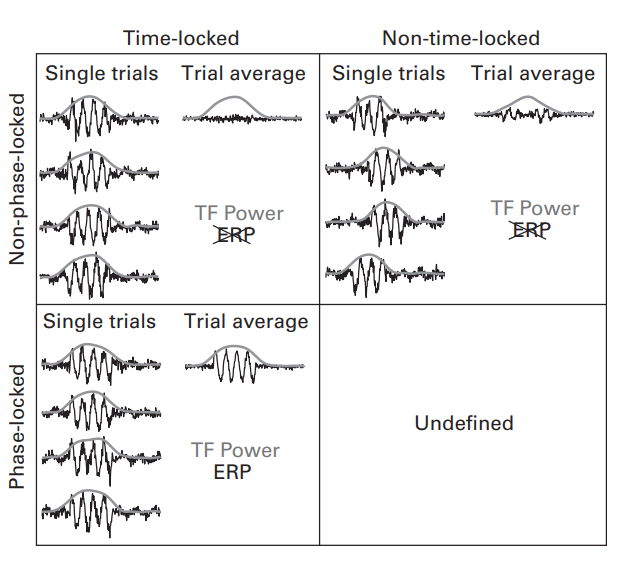

------------------------------------------------------------------------------------------------------

### **Ways to View Time-Frequency Results**

See time-frequency results as a three-dimensional (3-D) cube:

*frequency slice: Power vs Frequency*

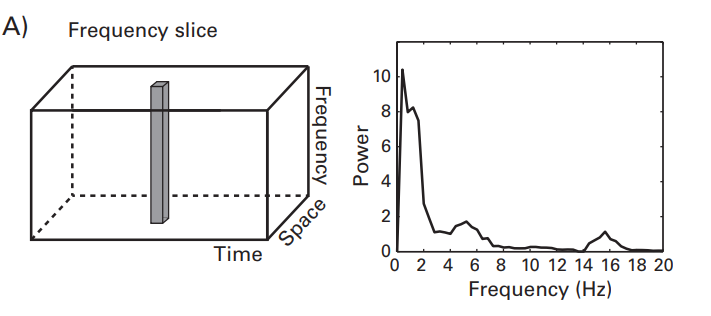

*Time slice: *one frequency band is selected, and activity at that frequency band is plotted over time  (*Note: These plots are useful for comparing activity across multiple conditions or electrodes and when there is an a priori reason to focus on a specific frequency band.*)

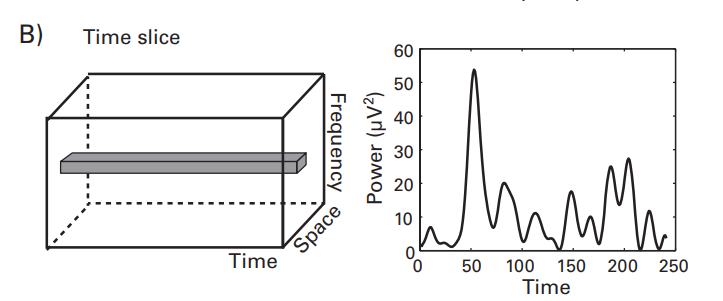

*Space slice: *data are shown at one time-frequency point, or the average over multiple adjacent time-frequency points, over electrodes in a topographical plot.

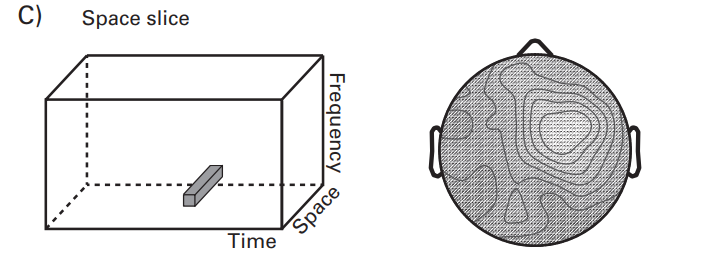

*Time-frequency slice: *data can be shown in a time-frequency plot. In time-frequency plots, time is on the *x*-axis and frequency is on the *y*-axis. (*Note: The color of the plot (also known as the z-axis or the depth) reflects some feature of the time-frequency data, such as power, phase clustering, connectivity, or correlation coefficient.*)

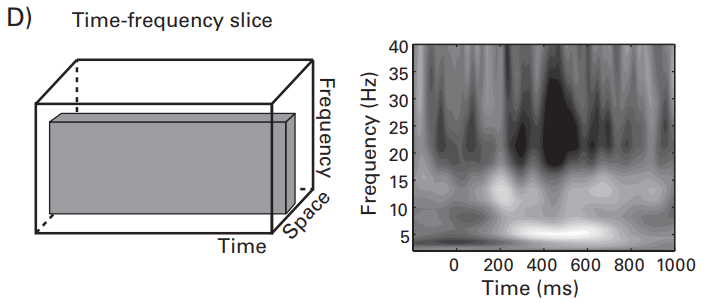

-----------------------------------------------------------------------------------------------------

### Time-Frequency Visualization

  tfviewerx MATLAB code for tfviewerx.fig
     USAGE:
  	tfviewerx(time,freq,DATA,chanlocs[,title]);
 
 	   time     : vector of time points
 	   freq     : vector of frequencies (e.g., of wavelet convolution)
 	   DATA     : channels X frequency X time matrix
 	   chanlocs : eeglab chanlocs structure
 	   title    : (optional) string title for figure
 
  written by mikexcohen@gmail.com



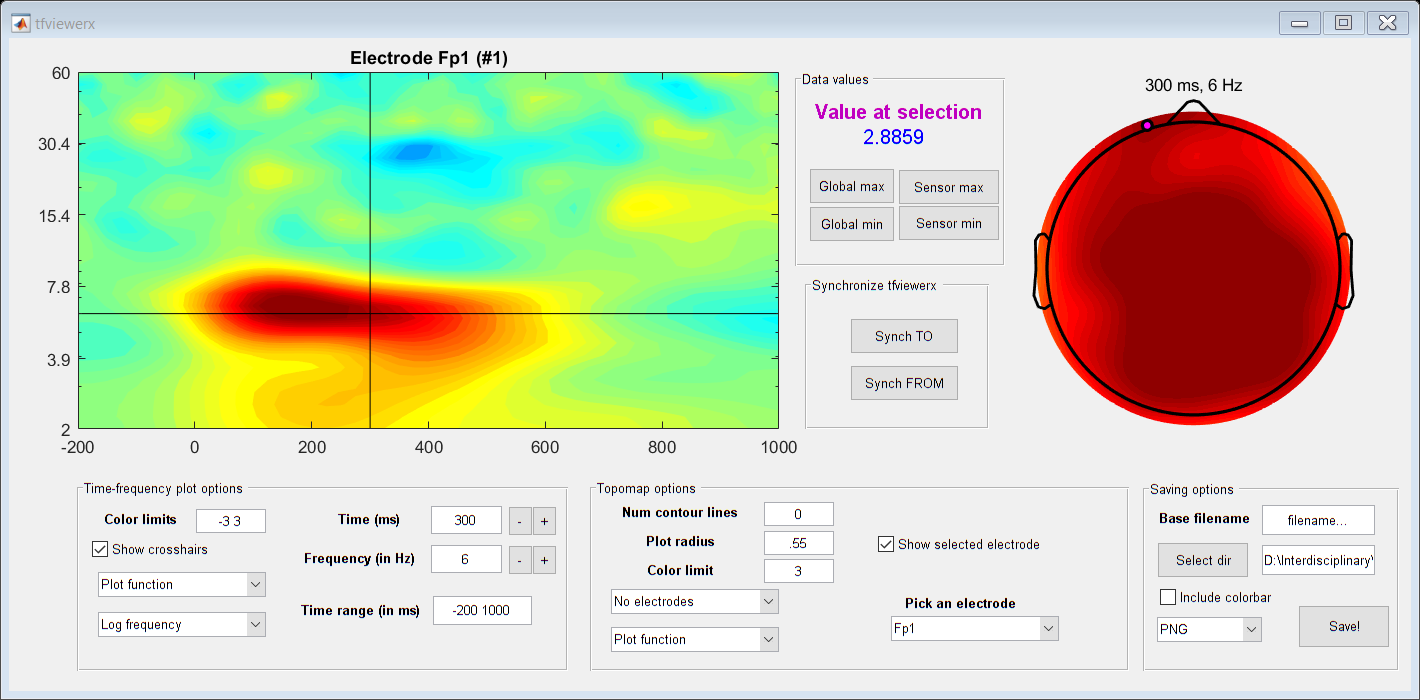

% You can use a function written by Mike Cohen "tfviewerx"

%    USAGE:
% 	tfviewerx(time,freq,DATA,chanlocs[,title]);
%
%	   time     : vector of time points
%	   freq     : vector of frequencies (e.g., of wavelet convolution)
%	   DATA     : channels X frequency X time matrix
%	   chanlocs : eeglab chanlocs structure
%	   title    : (optional) string title for figure
% Or you can use with pre existing data by simply run:
tfviewerx()

----------------------------------------------------------------------------------------------

### How to View and Interpret Time-Frequency Results  

*Step 1: Determine what is shown in the plot*  (Power? Scale?)

*Step 2: Inspect the ranges and limits of the plot*  (Symmetric vs Asymmetric)

*Step 3: Inspect the results*  (Is there activity at multiple frequencies and time windows, or is the activity all centered in one time-frequency “ blob ”?)

*Step 4: Link the results to the experiment (or to patient groups or gene or drug treatment, or whatever the independent variable is)*  

*Step 5: Understand the statistical procedures used to support the interpretations*  (Exploratory driven or Hypothesis driven)

(*Note: Exploratory analyses might lack the sensitivity to detect subtle features of the results, and hypothesis-driven analyses might miss important features of the results that were not predicted by the theory.*)

### ------------------------------------------------------------------------------------------------------

### **Things to Be Suspicious of When Viewing Time-Frequency Results**  

### 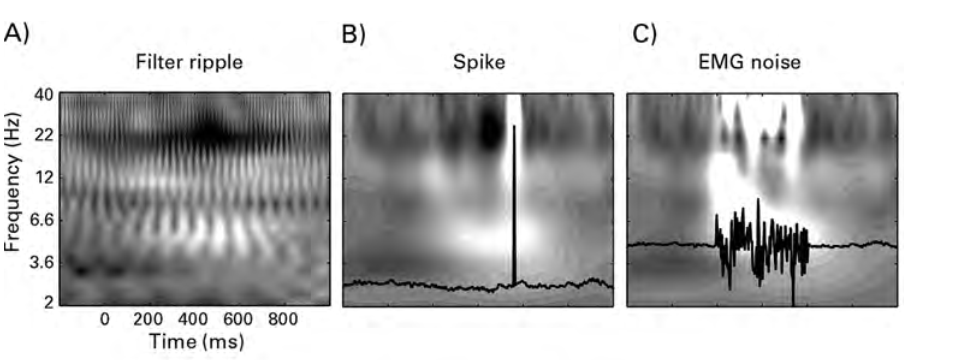

### 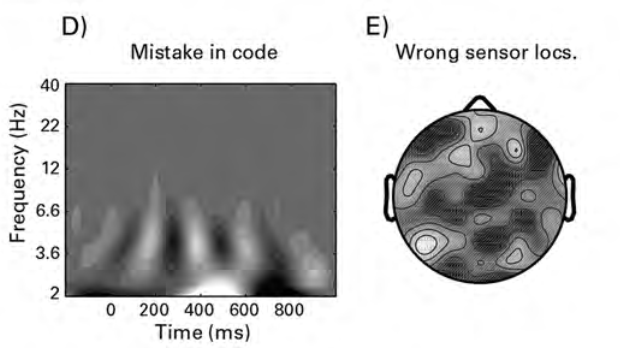

A. This can happen if the filter widths are too narrow or if the filter was applied to too little data, thus causing edge artifacts.

B. Brief and large-power effects at high frequencies could be driven by EEG artifacts such as amplifier saturation or a noise spike from a bad electrode.

C. Broadband effects that span many “ classical ” frequency ranges could be due to mechanical noise or excessive muscle activity from the jaw or neck.

D. Very fast color changes over time or frequency could be a mistake in the analysis (in this case, the real part of the analytic signal was plotted rather than power).

E. Strange topographical distributions that contain many peaks might be due to noisy or bad electrodes or to an incorrect mapping between electrode label and physical location  (*Note: high-pass spatial filters such as the surface Laplacian will increase topographical localization and highlight local spatial features.*)

-----------------------------------------------------------------------------------------------------------------------